# Homework 4 (Solution) 

Math 3607

Tae Eun Kim

## Problem 1 (Log Product; LM 5.6)

Here we compute the product of all elements of $\mathbf{a} = (a_1, a_2, \ldots, a_n)^{\rm T}$


$$P_n = \prod_{i=1}^n a_i$$


using the sum of logarithms as

$\log\left\vert P_n \right\vert = \sum_{i=1}^n \log \left\vert a_i \right\vert$,

and then expressing $P_n$ in scientific notation $f \times 10^m$, where $|f| \in [1, 10)$ and $m$ is an integer. How do we obtain $f$ and $m$ from the sum of logs? Let $\lambda = \log \left| P_n \right| = m + (\lambda-m)$, where $m = \lfloor \lambda \rfloor$ is the integer part of $\lambda$ and $\lambda-m \in [0, 1)$ is its fractional part. Upon exponentiation (with base 10), we obtain

$\left| P_n \right| = 10^\lambda  = 10^{\lambda-m} \times 10^m$.

Note that the first term $10^{\lambda -m}$ is in $[1, 10)$, so it must correspond to $| f |$.  In addition, $m$ is the same $m$ that appears in the scientific notation. In short, the procedure can be summarized as follows:

- Compute the sum of logs of absolute value of elements; call it $\lambda$. In doing so, keep track of the sign of each term. If an element is 0, the answer is 0 so set $f = 0$ and $m = 0$ and exit the program.

- Determine the integer part $m$ and the fractional part $\lambda -m$of $\lambda$.

- $m$ is found in the previous step; $f = \pm10^{\lambda -m}$ where the sign is determined by the number of negative elements. 

Below is an example script. 

We can do better without using any loop. (This is the style that I want you to ultimately acquire from this course.) 

**Solution: **(Function m-file)

Note: When asked to write a function m-file, use Code Example environment as shown above. If you need to call the function, you may include the function at the end of the live script. See the end of this file. 

**Explore.** What is the largest factorial computable in MATLAB?

n = 1;
while factorial(n) < inf
    n = n + 1;
end
n

n =    171

So $170!$ is the largest factorial computable and $n!$, with $n\ge 171$, overflows to infinity in MATLAB.

factorial(170)

ans =      7.25741561530799e+306

factorial(171)

ans =    Inf

(Recall that `realmax` is the largest double-precision floating-point number.)

realmax

ans =      1.79769313486232e+308

Question: How, then, would you go about calculating $200!$ using MATLAB?

## Problem 2 (Tiling with Sprial Polygons)

We have been working with this shapes several times and I hope by now you understand the underlying geometry as well as all programming techniques involved. See at the end of the current file for the code listing. 

### Illustration: Roles of Parameters

To make sure everyone understands what is really going on, take a look at the following examples:

m = 4;
rotate = 45;
shift = [0 0];

**Example 1:**

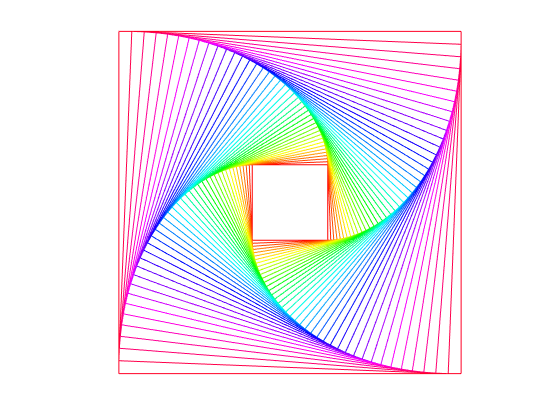

clf; spiralgon(m, 41, 2.25, rotate, shift);

Since the first one is drawn as a square with horizontal and vertical sides and since 40 additional squares are drawn with each rotated by $2.25^{\circ}$, the very last one is rotated by $40 \times 2.25^{\circ} = 90^{\circ}$, and so the last one also have horizontal and vertical sides. 

If you understand the previous paragraph, you will see why `n` and `d_angle` values were given as they were.

**Example 2:**

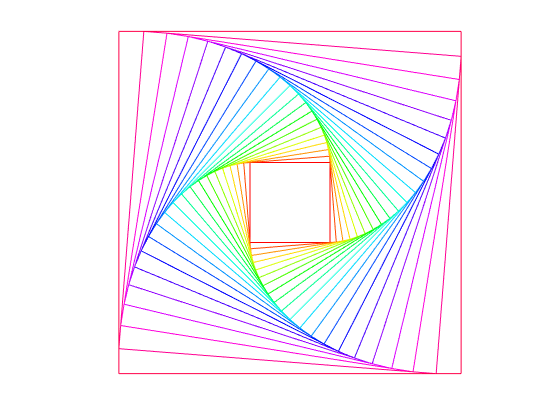

clf; spiralgon(m, 21, 4.5, rotate, shift);

Here, $20 \times 4.5^{\circ} = 90^{\circ}$. Once again, the outermost square has horizontal and veritcal sides, just as the innermost one. 

**Example 3:**

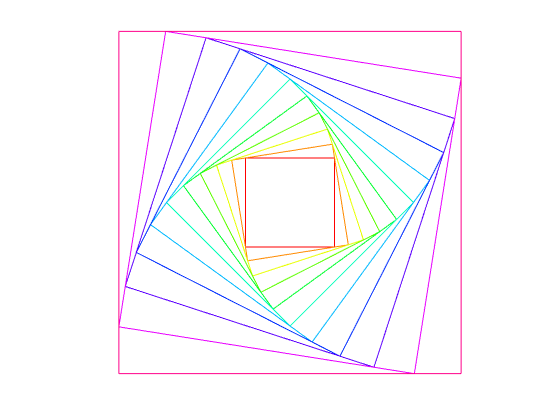

clf; spiralgon(m, 11, 9, rotate, shift);

Again, $10 \times 9^{\circ} = 90^{\circ}$.

**Observation. **As you can see, as long as `n` and `d_angle` values are chosen so that 


$$({\tt n-1}) \times {\tt d\_angle}$$


is a multiple of 90, the same kind of visual effect will be created. For instance,

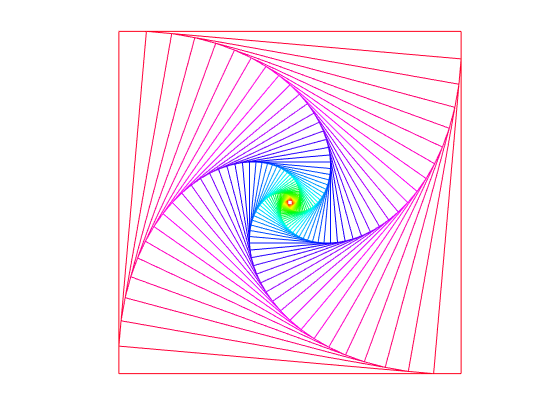

clf; spiralgon(m, 55, 5, rotate, shift);

Let us also confirm here that the code works with negative `d_angle` value. (We expect to see spirals drawn in the opposite orientation.)

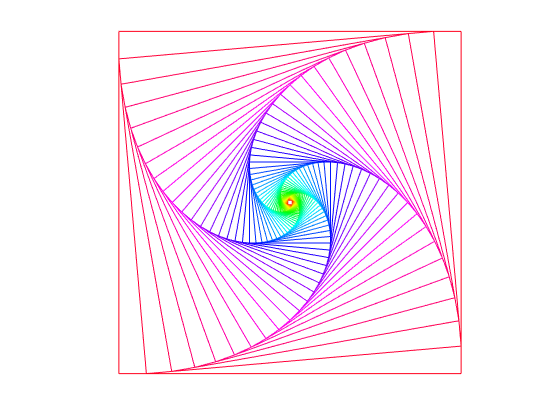

clf; spiralgon(m, 55, -5, rotate, shift);

This will become useful in a bit. 

### (a) Tiling with spiral triangles

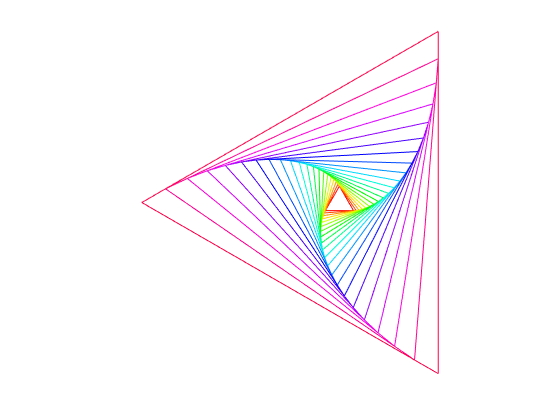

clf
n = 3; m = 21; d_angle = 4.5; d_rot = 90; shift = [0 0]';
V = spiralgon(n, m, d_angle, d_rot, shift);
hold off

shift = -V(:,1);
spiralgon(n, m, d_angle, d_rot, shift);

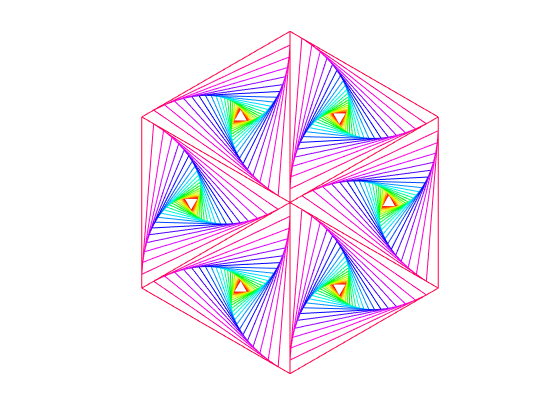

R = [cosd(60) -sind(60);
    sind(60)  cosd(60)];
for i = 2:6
    d_rot = d_rot + 60;
    shift = R*shift;
    spiralgon(n, m, d_angle, d_rot, shift);
end

### (b) Tiling with spiral squares

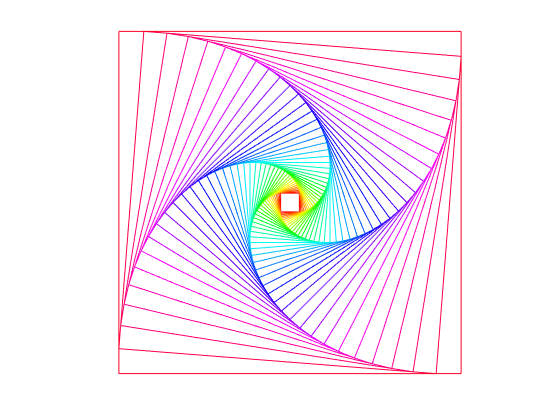

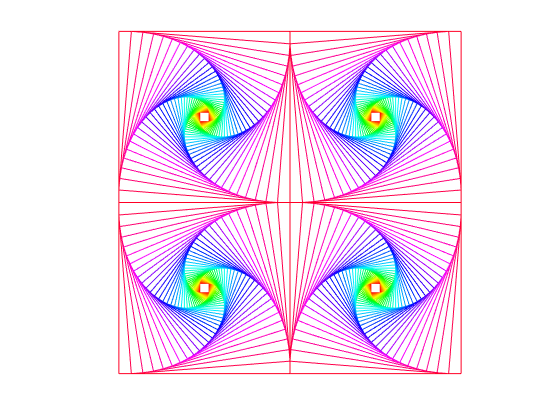

clf
n = 4; m = 41; d_angle = 4.5; d_rot = 45; shift = [0 0]';
V = spiralgon(n, m, d_angle, d_rot, shift);
hold off

shift = -V(:,1);
R = [0 -1;     % 90-degree rotation
    1  0];
for i = 1:4
    if i > 1
        shift = R*shift;
    end
    spiralgon(n, m, (-1)^i*d_angle, d_rot, shift);
end

### (c) Tiling with spiral hexagons

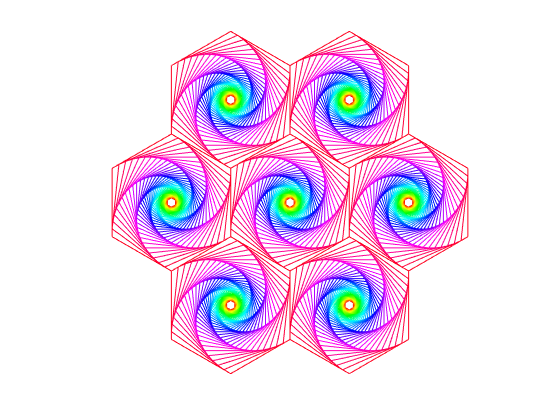

clf
V = spiralgon(6, 51, 6, 30, [0 0]);
for i = 1:6
    rotate = sum(V(:,i:i+1), 2);
    spiralgon(6, 51, 6, 30, rotate);
end

## Problem 3 (LM 9.3--3a)

format long g

**Successor of 8:**

(8 + 4*eps) - 8
(8 + 4.01*eps) - 8

Observe that the gap between `8 + 4.01*eps` and `8 `is not `4.01*eps`, but rather `8*eps.`

8*eps

**Predecessor of 16:**

16 - (16 - 4.01*eps)
16 - (16 - 4*eps)

kappa =          0.250167787600418         0.125000028131124         0.083333332387735        0.0625053720585748


Note that `16 - 4*eps` is registered to be the same as `16` in MATLAB while `16 - 4.01*eps` is rounded down to `16 - 8*eps`. This is how we know that `16 - 8*eps` comes immediately before `16` on the floating-point number system. 

**Neighbors of** $2^{10}$:

The gap between $2^{10}$ and the next floating-point number is $2^{10}  \cdot {\tt eps} = 2^{-42}$.

(2^10 + 2^9*eps) - 2^10
(2^10 + (2^9+1)*eps) - 2^10
2^(-42)

          x        abs error        rel error


 ---------------------------------------------


 2.7308e+01   4.61852778e-14   1.15463195e-14
 1.4905e+03   1.71089809e-10   4.27724522e-11
 8.1377e+04   1.37072186e-07   3.42680466e-08
 4.4431e+06   1.37512880e-03   3.43782200e-04


The gap between $2^{10}$ and the one before is $2^{9} \cdot {\tt eps} = 2^{-43}$.

2^10 - (2^10 - 2^8*eps)
2^10 - (2^10 - (2^8+1)*eps)
2^(-43)

## Problem 4 (9.3--10)

format long e

          x        abs error        rel error


 ---------------------------------------------


 2.7308e+01 0.0000000000e+00 0.0000000000e+00
 1.4905e+03 0.0000000000e+00 0.0000000000e+00
 8.1377e+04 0.0000000000e+00 0.0000000000e+00
 4.4431e+06 0.0000000000e+00 0.0000000000e+00


(a) Since $e^x = 1 + x + \frac{1}{2} x^2 + \cdots = \sum_{j=0}^\infty \frac{x^j}{j!}$, the limit is clearly 1.

$\lim_{x \to 0} f(x) = \lim_{x \to 0} \frac{\sum_{j=1}^\infty x^j / j!}{x} = \lim_{x \to 0} \sum_{j=1}^{\infty} \frac{x^{j-1}}{j!} = 1$.

(b) The following are used commonly in all subparts.

k = [1:20]';
x = 10.^(-k);

    (i) Note the use of elementwise division below.

fx = (exp(x) - 1)./x;

    (ii) In our textbook, $\log$ denotes the natural log $\ln$, and so the denominator $\log e^x = \ln e^x = x$.

f1x = (exp(x) - 1)./log(exp(x));

    (iii) The function `expm1` computes "exponental function $e^x$ minus 1". 

f2x = expm1(x)./x;

Let's package the results together simply using `disp`.

disp([x fx f1x f2x])

The first one $f(x)$ suffers horribly from the catastrophic cancellation since $e^x \approx 1$ for small $x$. To understand why $f_1(x)$ is doing a better job, note that the denominator $\log e^x$, for small $x$, behaves as follows:

$\log e^x = \log ( 1 + x + x^2/2 + \cdots ) = x + \text{(higher-order terms)}$.

Another round of power-series-fu reveals that

 $f_2(x) = (e^x - 1)/\log(e^x) = (x + x^2/2 + x^3/6 + \cdots)/(x + \cdots) = 1 + \text{(higher-order terms)}$,

and this is why MATLAB is much more tamed with this encoding. However, when $x$ gets sufficiently small, $e^x$ gets very close to 1 to a point that is not distinguishable on the floating-point number system. In our experiment, that happened when $k \ge 16$:

x_small = 1e-16;
exp(x_small)

When this is fed into $\log$, it outputs zero resulting in NaN.

log(exp(x_small))

This explain why we had NaN's for the last 5 results ($16 \le k \le 20$).

The function `expm1 `was designed to avoid the catastrophic cancellation occurring in calculating $e^x - 1$ for small $x$. See

help expm1

## Problem 5 (Inverting hyperbolic cosine)

t = -4:-4:-16;
x = cosh(t);

(a) Let $f(x) = \log(x - \sqrt{x^2-1}) = \text{acosh}(x)$. Calculation shows that

$\kappa_f (x) = \left| \frac{xf'(x)}{f(x)} \right| = \left| \frac{x}{\sqrt{x^2-1}} \cdot \frac{1}{\log (x - \sqrt{x^2-1})} \right|$.

We evaluate the condition number at the entries of `x` by

f  = log(x - sqrt(x.^2-1));
fp = -1./sqrt(x.^2-1);
kappa = abs( x.*fp./f )

(b) We have already evaluted $t = f(x)$ in part (a), saved as `f`. We compare against the original values stored in `t`;

absErr = abs(f - t)';
relErr = absErr./abs(t);
for j = 1:length(x)
    if j == 1
        fprintf(' %10s %16s %16s\n', 'x', 'abs error', 'rel error')
        fprintf(' %45s\n', repmat('-', 1, 45))
    end
    fprintf(' %10.4e %16.8e %16.8e\n', x(j), absErr(j), relErr(j))
end

Note from the expression for $\kappa_f(x)$ that the condition number becomes large as $x$ increases because the denominator $(x - \sqrt{x^2-1}) \log(x - \sqrt{x^2-1}) \to 0$ as $x \to 0$. This explains why the numerical computation incur larger errors, both absolute and relative, when $x$ is large. 

(c,d) Let $g(x) = -2 \log \left( \sqrt{\frac{x+1}{2}} + \sqrt{\frac{x-1}{2}} \right)$. Analytically, $g(x) = f(x)$. Unlike $f(x)$, however, numerical evaluation of $g(x)$ is done much more stably:

g = -2*log(sqrt((x+1)/2) + sqrt((x-1)/2));
absErr = abs(g - t)';
relErr = absErr./abs(t);
for j = 1:length(x)
    if j == 1
        fprintf(' %10s %16s %16s\n', 'x', 'abs error', 'rel error')
        fprintf(' %45s\n', repmat('-', 1, 45))
    end
    fprintf(' %10.4e %16.8e %16.8e\n', x(j), absErr(j), relErr(j))
end

The key difference is that the expression for $g(x)$ does not involve any ill-conditioned steps whereas $f(x)$ requires a subtraction which is prone to catastrophic cancellation for large $x$ as seen in part (b).

## Functions Used

### Log Product

function [f, m] = logprod(a)
% LOGPROD computes the product of elements of  a  using
% sum of logs of its elements
% input: a
% output: f, m
if any(a==0)                 % if any of the elements is zero
    f = 0; m = 0;
    return
end
nrNeg = length(find(a<0));   % number of negative elements
sumLog = sum(log10(abs(a)));
f = (-1)^nrNeg * 10^(mod(sumLog, 1));
m = floor(sumLog);
end

### Spiral Polygon

function V =  spiralgon(m, n, d_angle, rotate, shift)
% FSPRIALGON plots spiraling regular m-gons
% input:   m = the number of vertices
%          n = the number of regular m-gon
%          d_angle = the degree angle between successive m-gons
%          (can be positive or negative)
%          rotate = the degree angle of rotation of the initial m-gon
%          shift = (2-vector) location of the center of all m-gons
% output:  V = the vertices of the outermost m-gon

th = linspace(0, 360, m+1) + rotate;
V = [cosd(th);
    sind(th)];
C = colormap(hsv(n));
scale = sind(90 + 180/m - abs(d_angle))/...
    sind(90 - 180/m);
R = [cosd(d_angle) -sind(d_angle);
    sind(d_angle) cosd(d_angle)];
% hold off
for i = 1:n
    if i > 1
        V = scale*R*V;
    end
    plot(V(1,:)+shift(1), V(2,:)+shift(2), 'Color', C(i,:))
    hold on
end
set(gcf, 'Color', 'w')
axis equal, axis off

end